# **Práctica 5: Diseño de controladores en campo frecuencial**

Las prácticas de la asignatura control por computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. Las sesiones P3 y P4 se dedican al diseño de controladores PID. Por último, en la práctica P5 se diseñarán controladores en campo frecuencial.

**OBJETIVO: Diseñar un controlador en el domino frecuencial de la posición de salida para la planta estudiada en las sesiones anteriores para que el sistema en lazo cerrado cumpla ciertas especificaciones en el dominio frecuencial.**

**En esta sesión el estudiante ha de:**

- **Diseñar un controlador por avance de fase.**

- **Verificar experimentalmente el sistema de control diseñado.**

% Alternar entre los datos del experimento y los del directorio Resultados
% Si desea usar los datos del directorio Resultados = false
% Si desea usar datos propios = true
useExperimentalData = false;

# Introducción

En esta práctica se presentan los controladores de avance y retraso de fase. Estos controladores se ponen se serie (cascada) con la planta a controlar y tienen como objetivo modificar el comportamiento del sistema en lazo cerrado. El sistema de control debe satisfacer ciertas especificaciones definidas en el dominio frecuencial mediante un margen de ganancia y/o un margen de fase. Para el diseño de controladores en el dominio frecuencial, los sistemas de tiempo discreto se transforman en sistemas similares de tiempo continuo y se antitransforman para tener un controlador digital. A continuación, se detalla la metodología para el diseño de controladores de avance o retraso de fase para sistemas de tiempo continuo; después se plantean cuatro ejercicios.

La función de transferencia genérica en s de un controlador de avance o retraso de fase viene dada por


$$G_c \left(s\right)=K\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}$$


La relación $\alpha =\frac{\omega_p }{\omega_z }$ para el caso $\omega_p >\omega_z$, o $\alpha =\frac{\omega_z }{\omega_p }$ para el caso $\omega_p <\omega_z$ se llama longitud del controlador.

**CONTROLADORES DE AVANCE DE FASE**

Corresponden al caso en que $\omega_z <\omega_p$  y sirven para mejorar la respuesta transitoria. En un cierto intervalo de frecuencias, incrementan (*avanzan*) la fase del sistema controlado. El siguiente procedimiento permite determinar cuánto se incrementará la fase y en qué frecuencia debe centrarse la acción del controlador.

Las ecuaciones que se deben verificar para que $\Phi_{\mathrm{md}}$ sea el margen de fase del sistema realimentado son:


$$\begin{array}{l}
|G_c \left(j\;\omega_c \right)||\mathrm{GH}\left(j\;\omega_c \right)|=1\\
180+\mathrm{arg}\left(G_c \left(j\;\omega_c \right)\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\gamma_d 
\end{array}$$


Tomando $\omega_c =\sqrt{\omega_z \omega_p }=\omega_z \sqrt{\alpha }$ se pueden escribir como


$$\begin{array}{l}
|G_c \left(j\;\omega_z \sqrt{\alpha }\right)||\mathrm{GH}\left(j\;\omega_z \sqrt{\alpha }\right)|=1\\
180+\mathrm{arg}\left(\frac{\alpha -1}{2\sqrt{\alpha }}\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_z \sqrt{\alpha }\right)\right)=\Phi_{\mathrm{md}} 
\end{array}$$


El diseño del controlador se realiza buscando una solución aproximada del sistema de ecuaciones anterior y comprobando finalmente que el sistema en lazo cerrado satisface las especificaciones. Es un método de solución por prueba y error. La solución aproximada se obtiene resolviendo:


$$\begin{array}{l}
\theta_c =\Phi_{\mathrm{md}} +\Delta -\Phi_{\mathrm{GH}} \\
\alpha =\frac{1+\mathrm{sin}\;\theta_c }{1-\mathrm{sin}\;\theta_c }\\
|\mathrm{GH}\left(j\;\omega_c \right)|=\frac{1}{\sqrt{\alpha }}
\end{array}$$


donde $\Phi_{\mathrm{GH}}$ es el margen de fase del sistema en lazo abierto multiplicando por la ganancia estacionaria del controlador y $\Delta$ es un margen adicional de seguridad que introduce dado que se resuelve un sistema de ecuaciones aproximado y ninguna parte del sistema es exacta. La solución proporciona el máximo avance de fase proporcionado por el controlador, $\theta_c$, la longitud del controlador $\alpha$ y la frecuencia central $\omega_c$.

Las pulsaciones $\omega_z$ y $\omega_p$ se obtienen de $\alpha$ y $\omega_c$.


$$\omega_z =\frac{\omega_c }{\sqrt{\alpha }},\;\;\;\;\;\omega_p =\omega_c \sqrt{\alpha }=\omega_z \alpha$$


COMENTARIOS:

En caso de obtener $\theta_c >60$ se toma $k$ de manera que $\frac{\theta_c }{k}<60$, se diseña el controlador con $\frac{\theta_c }{k}$ y se aplica


$$G_c ={\left(\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}\right)}^k$$


Previamente la ecuación anterior se deberá reescribir como


$$|\mathrm{GH}\left(j\;\omega_c \right)|=\frac{1}{{\left(\sqrt{\alpha }\right)}^k }$$


**CONTROLADORES DE RETRASO DE FASE**

En este caso $\omega_p <\omega_z$ y sirven para mejorar la precisión en estado estacionario. El calificativo de retraso de fase proviene de que, en un cierto intervalo de frecuencias, el controlador reduce (*retrasa*) la fase del sistema controlado. Como en el caso anterior las ecuaciones que debe satisfacer el sistema controlado son:


$$\begin{array}{l}
|G_c \left(j\;\omega_c \right)||\mathrm{GH}\left(j\;\omega_c \right)|=1\\
180+\mathrm{arg}\left(G_c \left(j\;\omega_c \right)\right)+\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\gamma_d 
\end{array}$$


En este caso se determina la frecuencia $\omega_c$ que proporcionaría el margen de fase deseado del sistema de control y se calcula $\alpha$ de manera que $\omega_c$ sea la frecuencia de corte a 0dB de este sistema. El controlador se centra suficientemente a la izquierda de $\omega_c$ para que su efecto sea inapreciable en la fase de $|G_c \mathrm{GH}\left(j\;\omega_c \right)|$. Como en el caso de los controladores por avance de fase, el procedimiento no es exacto sino aproximado, razón por la que hay que introducir un margen adicional de seguridad y hacer una comprobación al final.

Las variables $\theta_c ,\omega_c$ y $\alpha$ se obtienen resolviendo las ecuaciones:


$$\begin{array}{l}
\theta_c =\gamma_d +\Delta -180\\
\mathrm{arg}\left(\mathrm{GH}\left(j\;\omega_c \right)\right)=\theta_c \\
\alpha =|\mathrm{GH}\left(j\;\omega_c \right)|
\end{array}$$


Finalmente,


$$\omega_z =\frac{\omega_c }{10},\;\;\omega_p =\frac{\omega_z }{\alpha }$$


COMENTARIOS:

- El algoritmo sólo se puede aplicar si la ecuación $\arg \left(\textrm{GH}\left(j\;\omega_c \right)\right)=\theta_c$ tiene solución.

- En el caso que $\alpha >12$ se diseña con $\alpha^{\wedge } =\sqrt[k]{\alpha }$ para $k$ natural suficientemente grande y se aplica


$$G_c ={\left(\frac{\frac{s}{\omega_z }+1}{\frac{s}{\omega_p }+1}\right)}^k$$


# Ejercicio 16: Determinación de los márgenes de ganancia y de fase del sistema.

Considere la planta del laboratorio con salida posición. Utilizando MATLAB, compruebe que los márgenes de ganancia y de fase del sistema digital y del sistema equivalente que resulta de aplicar la transformación bilineal coinciden.

% Parámetros de la planta
Kpot=1.62;
N=9;
K0=0.82/0.017;
tau0=0.26;
planta=tf([Kpot*K0/N],[tau0,1,0])


planta =
 
     8.682
  ------------
  0.26 s^2 + s
 
Continuous-time transfer function.



% Modelo de Tiempo discreto
Ts=0.01;
plantad=c2d(planta,Ts,'zoh') ;

% Transformada Bilineal
plantaw=d2c(plantad,'tustin') ;

% Comprobación de la coincidencia en el cálculo de los márgenes
display('Márgenes de la planta bilineal')

Márgenes de la planta bilineal


[Gmw,Pmw,Wcgw,Wcpw]=margin(plantaw)

Gmw = 23.1838

Pmw = 35.1259

Wcgw = 27.8243

Wcpw = 5.1783

display('Márgenes de la planta discreta')

Márgenes de la planta discreta


[Gmd,Pmd,Wcgd,Wcpd]=margin(plantad)

Gmd = 23.1858

Pmd = 35.1258

Wcgd = 27.6481

Wcpd = 5.1772

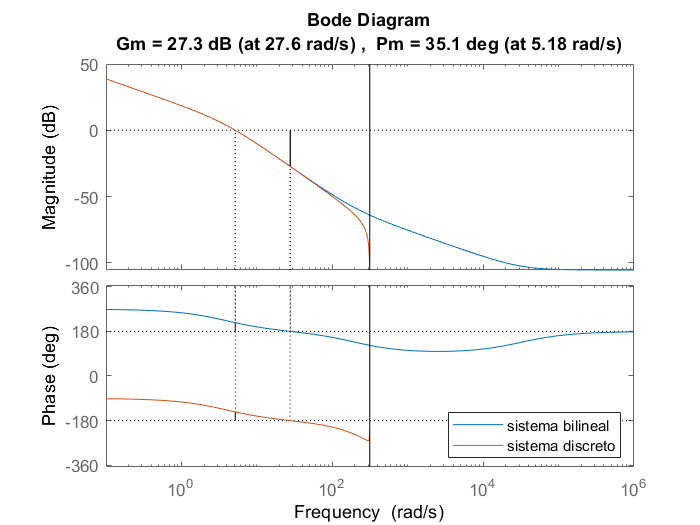

margin(plantaw)
hold on
margin(plantad)
legend('sistema bilineal','sistema discreto','Location', 'SouthEast')

Como se puede observar, los márgenes obtenidos mediante el comando *margin()* de los dos sistemas a analizar, son exactamente los mismos.

# Ejercicio 17: Diseño de un controlador de avance de fase.

Con la ayuda de MATLAB, diseñe un controlador de avance de fase que haga que el sistema de lazo cerrado, para el control de posición de la planta del laboratorio, con un periodo de muestreo Ts = 0.01, tenga un margen de fase de 45º y un error estático con una entrada en rampa del 10%. Considere un margen de fase adicional de seguridad de $\Delta =15º$.

% Parámetros de la planta
Kpot=1.62;
N=9;
K0=0.82/0.017;
tau0=0.26;
planta=tf([Kpot*K0/N],[tau0,1,0])


planta =
 
     8.682
  ------------
  0.26 s^2 + s
 
Continuous-time transfer function.



% Modelo de Tiempo discreto
Ts=0.01;
plantad=c2d(planta,Ts,'zoh') ;

% Transformada Bilineal
plantaw=d2c(plantad,'tustin') ;

% Cálculo de la ganancia necesaria
% Coeficiente de error de velocidad
errordes=0.1;
Kv=(1/errordes);

% Cálculo del incremento de ganancia necesaria
% (Ganancia del controlador)
Kvplanta=Kpot*K0/N;
Kcontrolador=Kv/Kvplanta

Kcontrolador = 1.1518

% Cálculo de la Margen de Fase
[Gm,Pm,Wcg,Wcp]=margin(Kcontrolador*plantaw)

Gm = 20.1290

Pm = 32.6959

Wcg = 27.8243

Wcp = 5.6375

% Cálculo de la Fase que debe agregar el controlador
gamma=45;
delta=15;
theta=(gamma+delta-Pm)* pi /180;

% Cálculo del parámetro alpha
alpha=(1+sin(theta))/(1-sin(theta));

% Búsqueda del punto donde el sistema tiene la ganancia 1/sqrt(alpha)
[aux1,aux2,aux3,wc]=margin(Kcontrolador*plantaw*sqrt(alpha));
wc

wc = 7.4975

% Colocamos el polo y el cero
wz=wc/sqrt(alpha); %Avance
wp=wz*alpha ;

%Construcción del controlador
Gcw=tf([1/wz,1],[1/wp,1]);

% Bilineal Inversa: Obtención del Controlador
Gcz=c2d(Gcw,Ts,'tustin')


Gcz =
 
  2.597 z - 2.481
  ---------------
    z - 0.8841
 
Sample time: 0.01 seconds
Discrete-time transfer function.



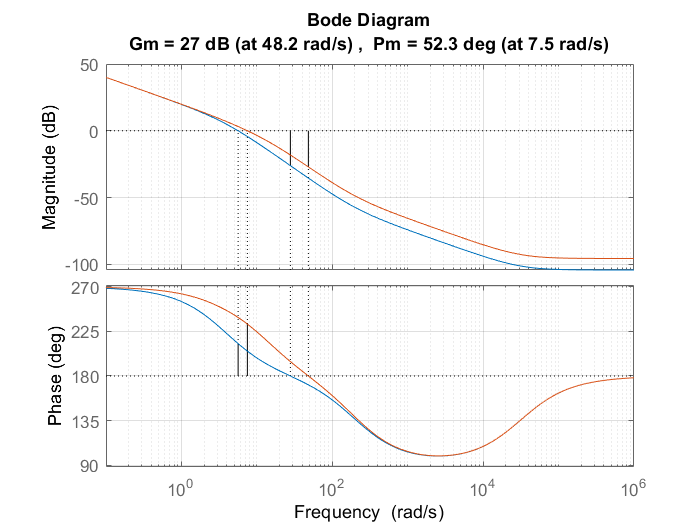

% Respuesta frecuencial en lazo abierto
% (Verificación del cumplimiento de las especificaciones)
figure
Gczplantad=series(Kcontrolador*Gcz,plantad);
Gczplantaw=d2c(Gczplantad,'tustin');
margin(Kcontrolador*plantaw)
hold on


margin(Gczplantaw)
grid

disp('mirad si os gusta el nuevo margen de fase ; pulse cualquier tecla')

mirad si os gusta el nuevo margen de fase ; pulse cualquier tecla


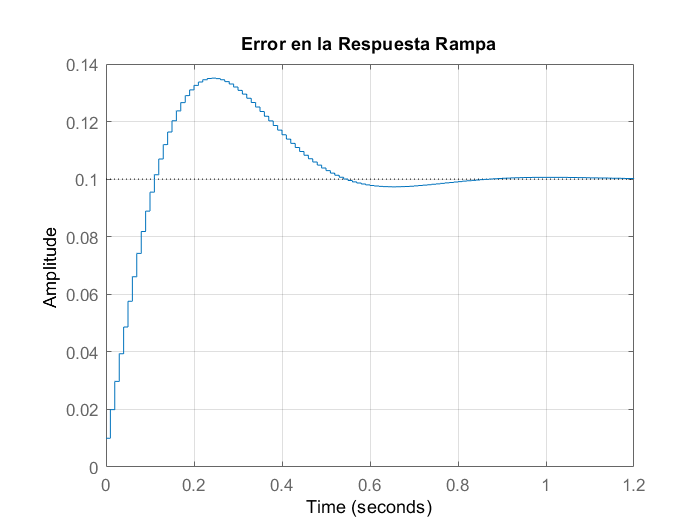

pause

% Construcción del Sistema en lazo cerrado
closed=feedback(Gczplantad,1);
err=1-closed;

% Verificación de la respuesta temporal
figure
grao=tf([1 0],[1,-1],Ts);
step(minreal(err*grao)*Ts ) ;
grid
title('Error en la Respuesta Rampa')

% Preparación de datos para Simulink 

disp('coeficientes de la función de transferencia del controlador de ganancia unitaria en z')

coeficientes de la función de transferencia del controlador de ganancia unitaria en z


Kc=dcgain(Gcz)

Kc = 1

Zc=zero(Gcz)

Zc = 0.9553

Pc=pole(Gcz)

Pc = 0.8841

# Ejercicio 18: Análisis en simulación.

- Compare los diagramas de bode del sistema en lazo abierto con el controlador diseñado añadiéndole retrasos de uno, dos, tres, ... periodos de muestreo. 

- ¿Cuántos periodos de retraso puede aguantar el sistema manteniendo la estabilidad? 

Ejecute el modelo P5_Ex19.slx, defina los parámetros del controlador diseñado. Vea la respuesta temporal del sistema.

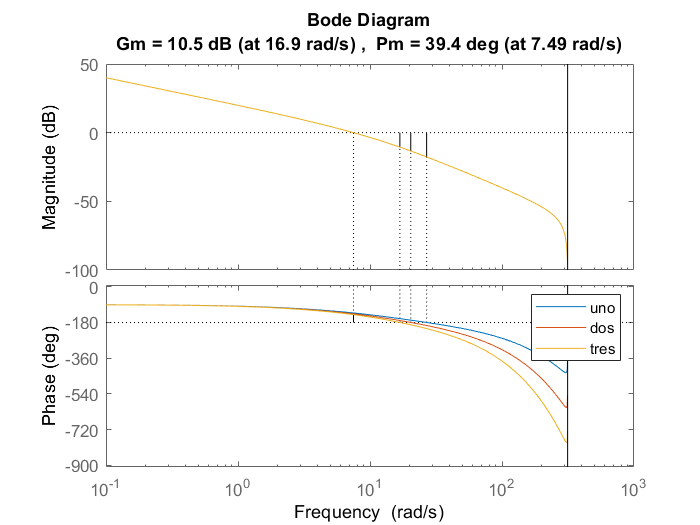

% Generación de los retardos
unret=tf([1],[1 0],Ts) ;
dosret=tf([1],[1 0 0],Ts) ;
tresret=tf([1],[1 0 0 0],Ts) ;

% Visualización de los diferentes diagramas de Bode
figure
margin(unret*Gcz*plantad*Kcontrolador)
hold all
margin(dosret*Gcz*plantad*Kcontrolador)
margin(tresret*Gcz*plantad*Kcontrolador)
legend('uno','dos','tres')

Creando más retrasos, podremos observar como a partir de retardos de 13 periodos de muestreo el sistema se vuelve inestable. Por otro lado, simulando el modelo P5_Ex19.slx podemos observar como en la respuesta a una entrada tipo rampa obtenemos un error de 0,01.

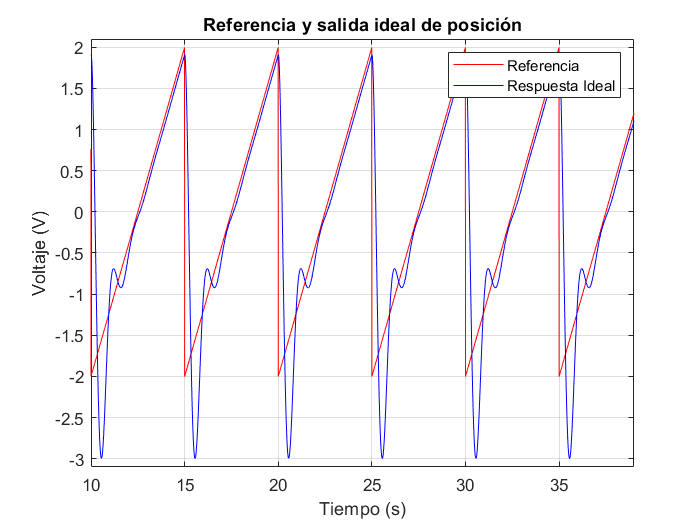

if useExperimentalData
    % Usar Simulink
    open P5_Ex19.slx
    run P5_Ex19.slx;
else
    FileName   = 'P5_real_ideal.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac5'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,2,:)],'r')
hold on; grid on;
plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,3,:)],'b')
xlim([10 39]); ylim([-3.1 2.1]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Referencia y salida ideal de posición');
legend('Referencia','Respuesta Ideal');

# Ejercicio 19: Implementación del controlador de avance de fase.

Ejecute el modelo P5_Ex20.slx y visualice el comportamiento del sistema de control experimental y compruebe la especificación relativa a la constante de velocidad.

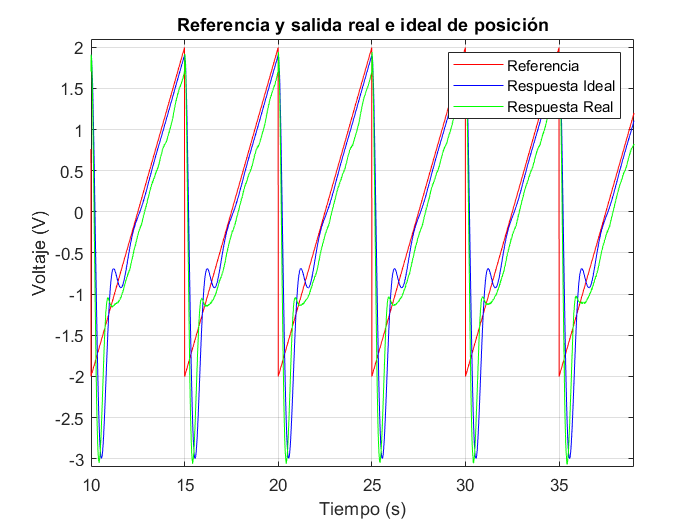

if useExperimentalData
    % Usar Simulink
    open P5_Ex19.slx
    run P5_Ex19.slx;
else
    figure
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,2,:)],'r')
    hold on; grid on;
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,3,:)],'b')
    plot(P5_real_ideal.time,[P5_real_ideal.signals.values(:,1,:)],'g')
    xlim([10 39]); ylim([-3.1 2.1]);
    xlabel('Tiempo (s)');
    ylabel('Voltaje (V)');
    title('Referencia y salida real e ideal de posición');
    legend('Referencia','Respuesta Ideal','Respuesta Real'); 
end

Como se puede observar, la salida real tiene un error constante frente a una entrada tipo rampa, pero la dinámica de la salida no es el mismo que el ideal, esta diferencia proviene de las dinámicas no modeladas del sistema. 